**Aplicación de un filtro ideal**

En este ejemplo se realizará el filtrado de una señal aplicando un filtro "ideal" en el dominio de la frecuencia.

¿Es posible aplicarloe n el dominio del tiempo?

Inicialmente se crea el espacio de tiempo dicreto y la señal a filtrar:

- se representarán 128 muestras

- la señal está compuesta por 2 frecuencias diferentes

N=128;
n= 0:N-1;
f1=1/32

f1 = 0.0313

f2=1/16

f2 = 0.0625

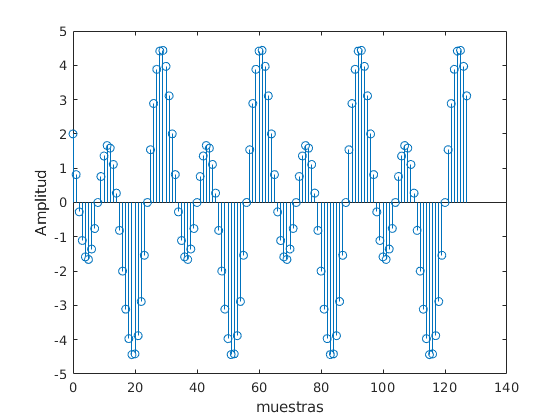

xn=2*cos(2*pi*f1*n)-3*sin(2*pi*f2*n);
figure('Name','señal x(n)')
stem(n,xn)
xlabel('muestras')
ylabel('Amplitud')

  A partir de las muestras de la señal se obtiene la representación en frecuencia mediante la FFT

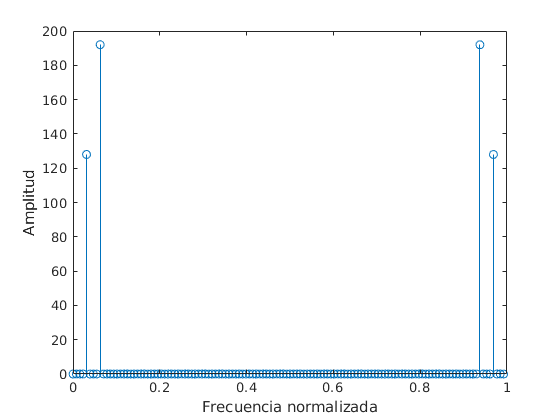

xk=fft(xn);
k=n/N;
figure('Name','Espectro (magnitud)')
stem(k,abs(xk))
xlabel('Frecuencia normalizada')
ylabel('Amplitud')

Observe los dos picos predominates ubicados en los valores correspondientes a f1 y f2.

Observe la relación existente entre el número de muestras y la amplitud de los armónicos.

A continuación se aplicará un filtro pasa-bajos directamente sobre el dominio de la frecuencia, observe que se aplica como un umbralq ue convierte en cero cualqier armónico por arriba de la frecuencia de corte

wcb=1/16% frecuencia de corte

wcb = 0.0625

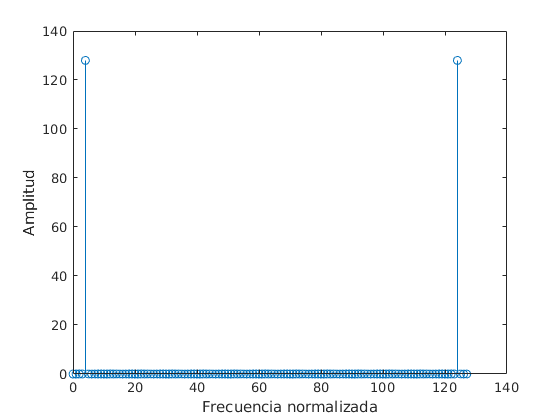

wct=floor(wcb*N);
xkfb=xk;
for i=1:N+1
    if (i>wct) && (i<N+2-wct)
        xkfb(i)=0; %espectro filtrado
    end
end
figure('Name','Espectro (magnitud) filtrado')
stem(n,abs(xkfb))
xlabel('Frecuencia normalizada')
ylabel('Amplitud')

Una vez se tiene el espectro filtrado de la señal, se procede a reconstruir la señal en el dominio temporal usando la FFT inversa

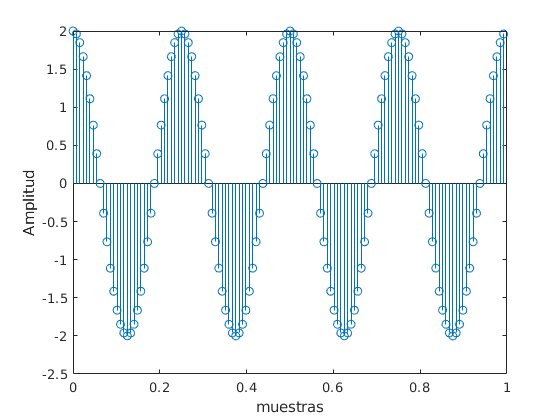

xnfb=ifft(xkfb);
figure
stem(k,xnfb)
xlabel('muestras')
ylabel('Amplitud')

Ahora se aplicará un filtro pasa-altos a la misma señal. Compare con el filtro pasa-bajos

wca=1/16% frecuencia de corte

wca = 0.0625

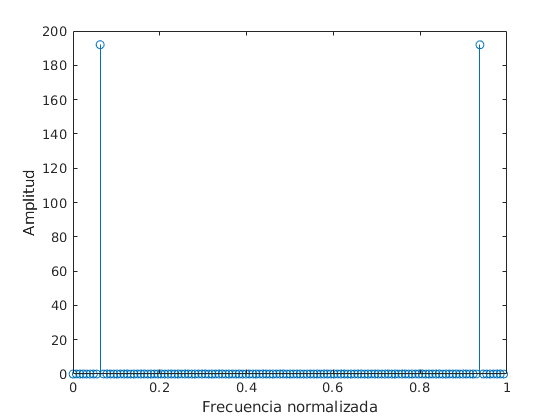

wct=floor(wca*N);
xkfa=xk;
for i=1:N
    if (i<wct) || (i>N+2-wct)
        xkfa(i)=0; %espectro filtrado
    end
end
figure('Name','Espectro (magnitud) filtrado')
stem(k,abs(xkfa))
xlabel('Frecuencia normalizada')
ylabel('Amplitud')

Una vez se tiene el espectro filtrado de la señal, se procede a reconstruir la señal en el dominio temporal usando la FFT inversa

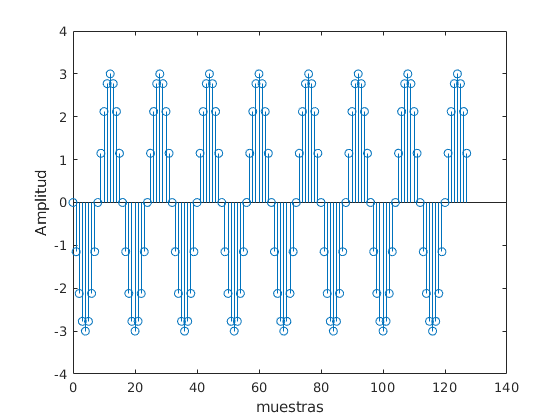

xnfa=ifft(xkfa);
figure
stem(n,xnfa)
xlabel('muestras')
ylabel('Amplitud')